tic
n = 2 % dimensions

n = 2

max_iterations = 1000000 % max_iteration

max_iterations = 1000000

value_error = 1e-5;
point_error = 1e-5;
center = [-5,-5];

gamma0 = 0.5 % init step size

gamma0 = 0.5000

gamma = gamma0;
alpha = 0.1*gamma % init test step size

alpha = 0.0500

directions = eye(2);
%init_vert = 6 * (rand(1,n) - 0.5) - 5
point = init_vert;
value = f(init_vert)

value = 3.5500

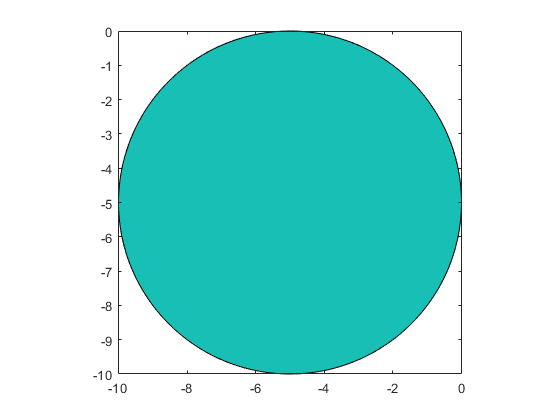

oracle_calls = 1;
prev_val = value;
prev_var = point;
s = 0;
h = zeros(n,1);

%plots
obj = zeros(max_iterations+1,1); %vol = zeros(max_iterations,1);
error = zeros(max_iterations+1,1); %vol = zeros(max_iterations,1);
figure(1);
[X,Y] = meshgrid(-10:0.1:0,-10:0.1:0);
circle = 25 - (X + 5).^2 - (Y + 5).^2;
contourf(X,Y,circle,[0,0]); axis equal; hold on;

points = zeros(max_iterations+1,2);
points(1,:) = init_vert;
%plot(init_vert(1),init_vert(2),'-x')

value_criterion = false;
variable_criterion = false;

## Optimization Loop

for iT=0:max_iterations
    gamma = gamma0 / (iT+1);
    alpha = 0.1*gamma;
    prev_val = value;
    prev_var = point;
    obj(iT+1) = value; 
    
    h = directions(mod(iT,n)+1,:);
    s = (f(point + alpha * h) - f(point)) / alpha * h;
    if (max(isnan(s)))
        s = 5*sign(point(mod(iT,n)+1) - center(mod(iT,n)+1));
    end
    point = point - gamma * s;
    value = f(point);
    oracle_calls = oracle_calls + 1;
    
    points(iT+2,:) = point;% plot(point(1),point(2),'-x')
    
    value_criterion = (abs(value - prev_val) < value_error);
    variable_criterion = (norm(point - prev_var) < point_error);
    error(iT+1) = abs(value - prev_val);
    if (value_criterion || variable_criterion)
        break;
    end
end
toc

Elapsed time is 0.452956 seconds.


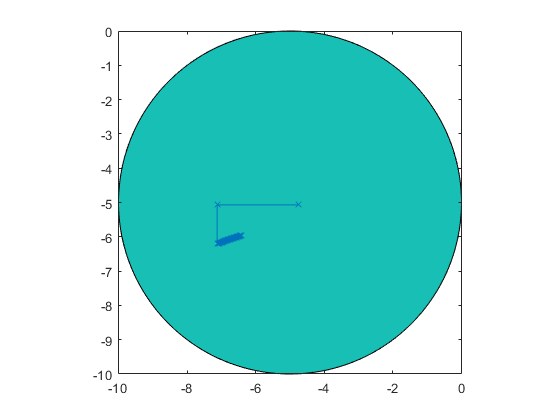

plot(points(1:iT+2,1),points(1:iT+2,2),'-x')
hold off; 

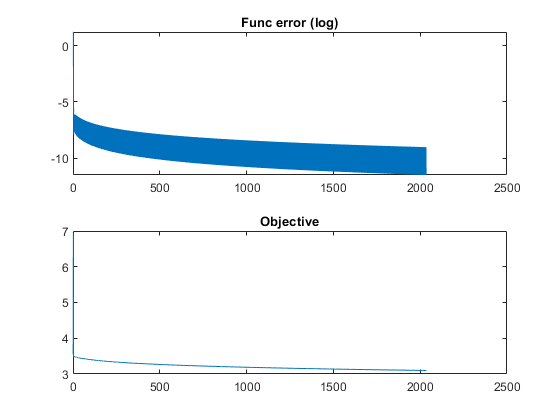

obj(iT+2) = value;
figure(2);  subplot(2,1,1); plot(log(error(1:iT+1)),'-'); title('Func error (log)');
            subplot(2,1,2); plot(obj(1:iT+2),'-'); title('Objective');